% Define the inductance value for the R-L circuit
L = 47e-6 

L = 4.7000e-05


% Define the input voltage value
vin = 1

vin = 1


% Define the transfer function g1 for the R-L circuit
% with a resistor value of R and an inductor value of L
g1 = tf(R , [L R ])

g1 =
 
        47
  --------------
  4.7e-05 s + 47
 
Continuous-time transfer function.




% Create a time vector for the step response plot
t = linspace (0, 10e-6, 1000)

t = 1.0e-05 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


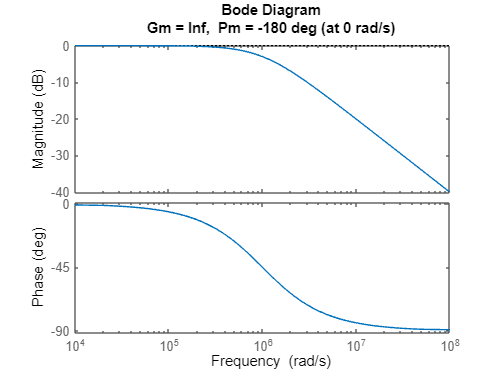


% Define the input voltage signal for the step response plot
Vin = ones(size(t));

% Plot the Bode plot of the transfer function g1
margin(g1);



%GAIN MARGIN 

%At high frequencies, the Bode plot of a system usually shows a straight line with a slope of -20 dB/decade (or -6 dB/octave) for the magnitude response. This is because the system's response is dominated by its high-frequency behavior, and at these frequencies, the transfer function can be approximated as a first-order system.

%At low frequencies, the Bode plot may deviate from a straight line due to the presence of poles and zeros in the transfer function

%The greater the Gain Margin (GM), the greater the stability of the system. The gain margin refers to the amount of gain, which can be increased or decreased without making the system unstable.


%the line that goes from 0 to -40 magnitude at 10^8 frequency may represent the high-frequency behavior of a system, where the transfer function can be approximated as a first-order system with a cutoff frequency of 10^8. On the other hand, the downward-curving line at 10^5 frequency on the phase axis may represent the presence of a pole or zero in the transfer function, causing a deviation from the expected -90 degree phase shift for a first-order system.



% Plot the zeros of the transfer function g1
zero(g1)


ans =

  0×1 empty double column vector




% Plot the poles of the transfer function g1
pole(g1)

ans = -1.0000e+06

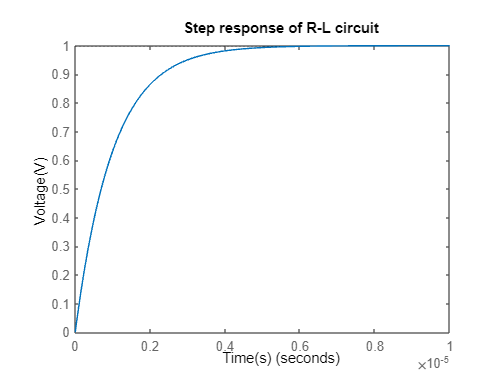


% Plot the step response of the R-L circuit
step(g1, t);

% Add a title to the step response plot
title('Step response of R-L circuit' )

% Label the x-axis of the step response plot
xlabel ('Time(s)');

% Label the y-axis of the step response plot
ylabel('Voltage(V)');


%RL CIRCUIT RESPONSE 

%At the start of the graph, the voltage steadily increases, indicating that the circuit is charging. This charging behavior occurs as current flows through the circuit and builds up a magnetic field around the inductor, which causes the voltage across the inductor to rise.
% at 0.8 volts the inductor is fully charged and the voltage begins to
% flatten until 1 volts is reached 


% Define the resistance, inductance, and capacitance values for the R-L-C circuit
R2 = 230        

R2 = 230

L2 = 47e-6  % the inductance value is 47 microhenries

L2 = 4.7000e-05

C2 = 10e-9  % the capacitance value is 10 nanofarads

C2 = 1.0000e-08


% Define the transfer function g for the R-L-C circuit
% with a resistor value of R2, an inductor value of L2, and a capacitor value of C2
g = tf( 1, [L2*C2 R2*C2 1])

g =
 
               1
  ---------------------------
  4.7e-13 s^2 + 2.3e-06 s + 1
 
Continuous-time transfer function.




% Create a time vector for the step response plot
t1 = linspace (0, 20e-6, 1000)

t1 = 1.0e-04 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


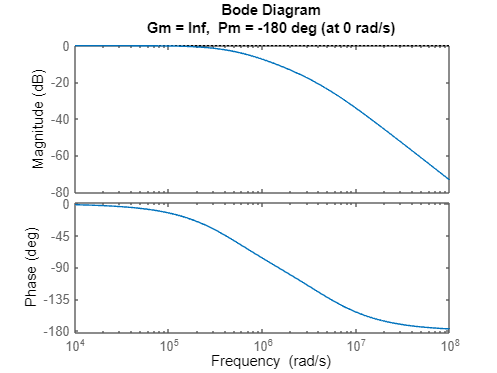


% Define the input voltage signal for the step response plot
Vin = ones(size(t1));

% Plot the Bode plot of the transfer function g
margin(g)


% Plot the zeros of the transfer function g
zero(g)


ans =

  0×1 empty double column vector




% Plot the poles of the transfer function g
pole(g)

ans = 1.0e+06 *

   -4.4113
   -0.4823


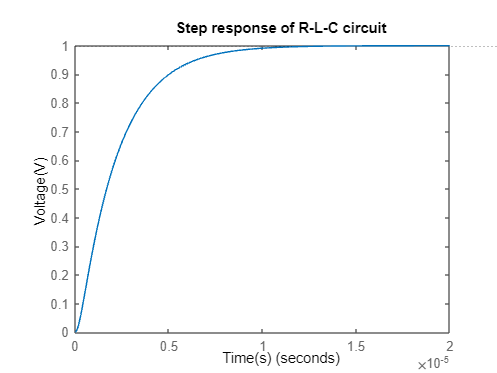


% Plot the step response of the R-L-C circuit
step(g, t1);

% Add a title to the step response plot
title('Step response of R-L-C circuit' )

% Label the x-axis of the step response plot
xlabel ('Time(s)');

% Label the y-axis of the step response plot
ylabel('Voltage(V)')